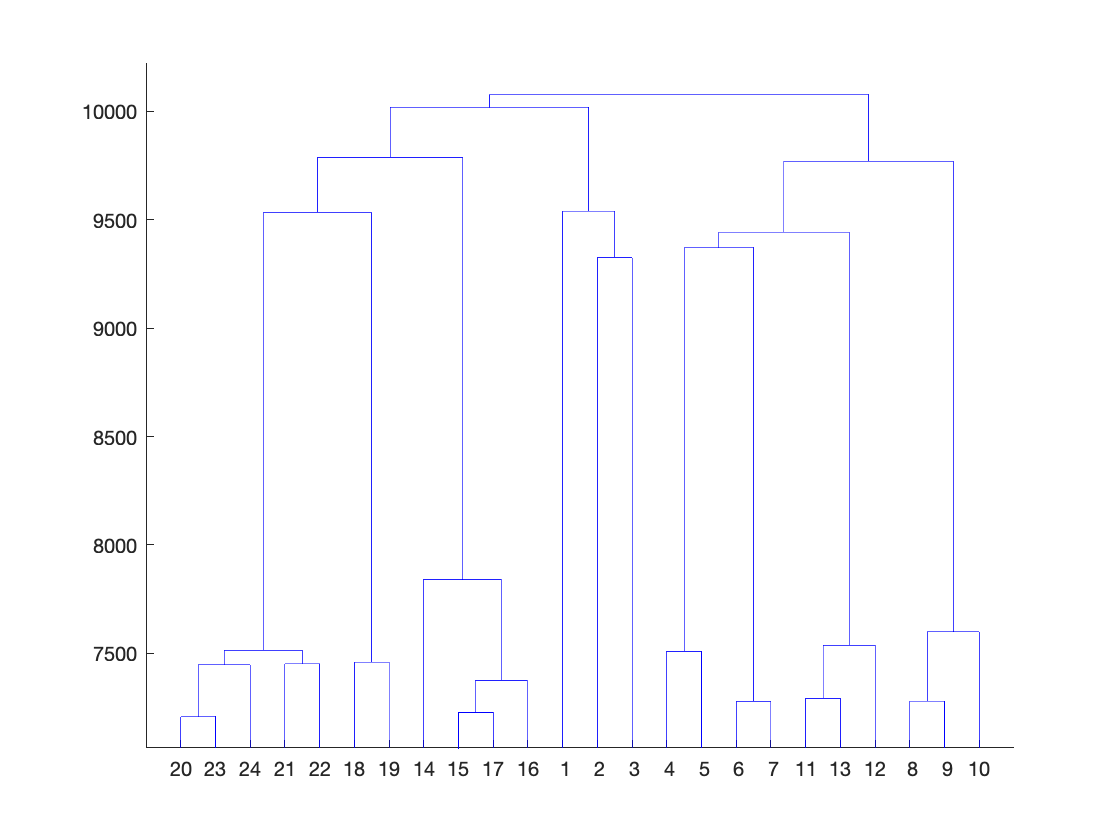

% Genetic data:

load g_new.mat

% 4000 genes are the dimensions/variables here, through which we have to
% identify linkages in individuals across generations.

% Gen 4 data: g4, 4000 genes x 24 individuals

% Linkages in g4 
Z = linkage(g4','complete','squaredeuclidean');
% Z_tot = linkage(g4','average','squaredeuclidean');
figure
dendrogram(Z,N4tot);

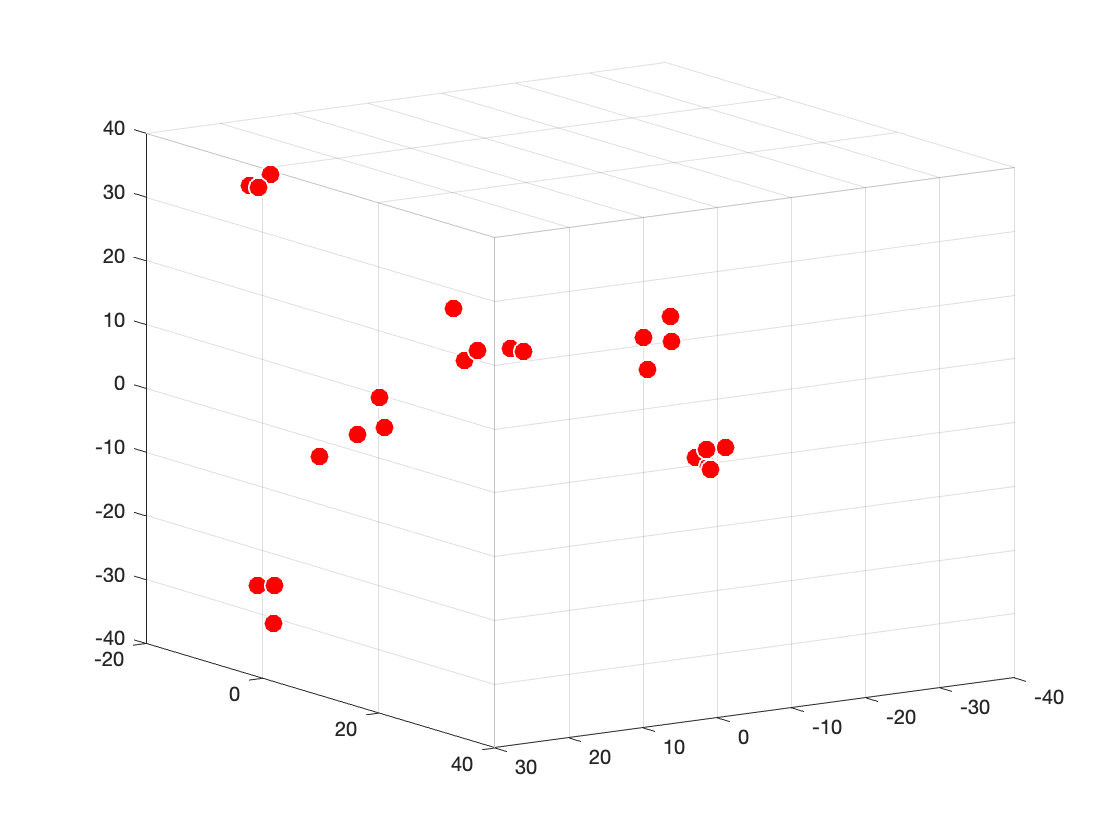


% Dimensionality reduction using PCs
% ---------------------------------
% Here P = 4000 dimensions/variables, and N = 24 observations/ data-points
% Similarly, g_tot across all 4 generations have N=40 individuals

% This is not a well-constrained problem (N<<P), so we will only get N or
% N-1 PCs/new dimensions returned through the PCA analysis



[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(g4');
% The number of PCs returned for g_tot are 23 or 24 in columns (depending 
% on parameters), each with 4000 weights along original dimensions
% Scores are the 24 observations/individuals projected along the PC axis. 
% Examine the first 3 scores
figure; 
scatter3(SCORE(:,1),SCORE(:,2),SCORE(:,3),100, 'filled','MarkerFaceColor','r',...
                        'MarkerEdgeColor','w')

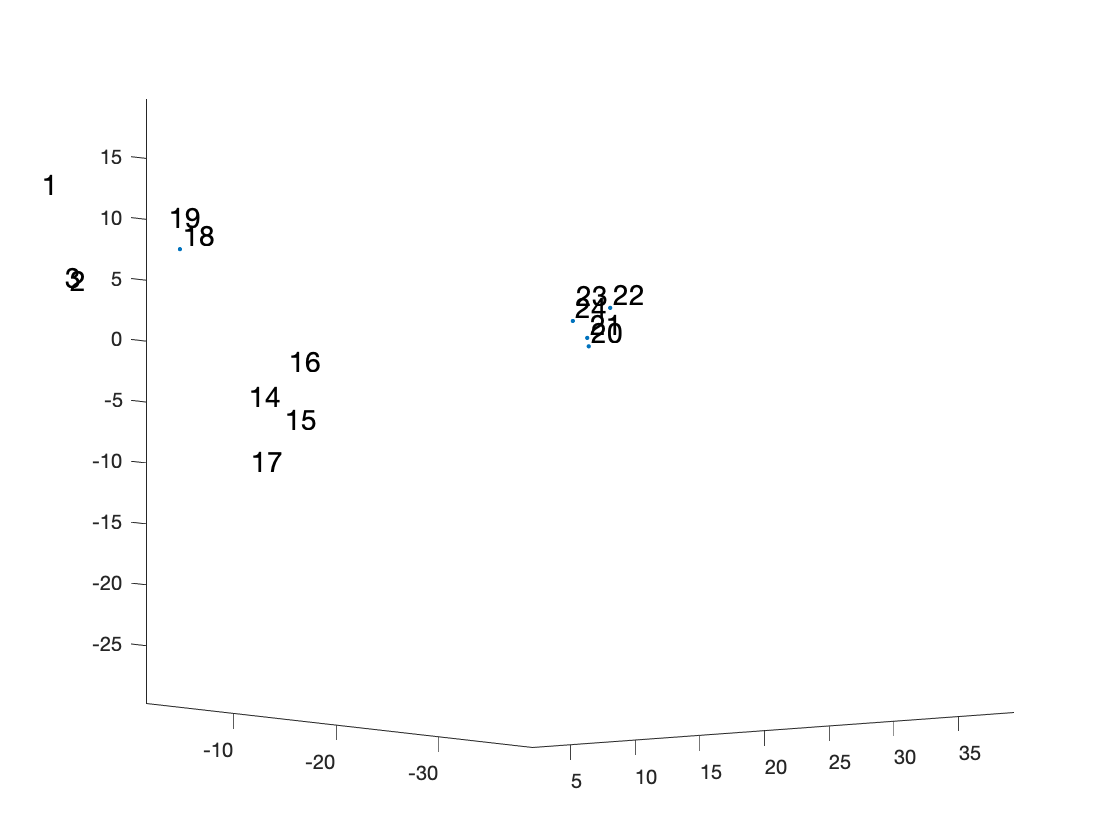

% Label individuals
figure;
plot3(SCORE(:,1),SCORE(:,2),SCORE(:,3),'.')
hold on
for i = 1:length(SCORE)
    text(SCORE(i,1)+1,SCORE(i,2)+1,SCORE(i,3)+1,num2str(i),'FontSize',14)
    hold on
end

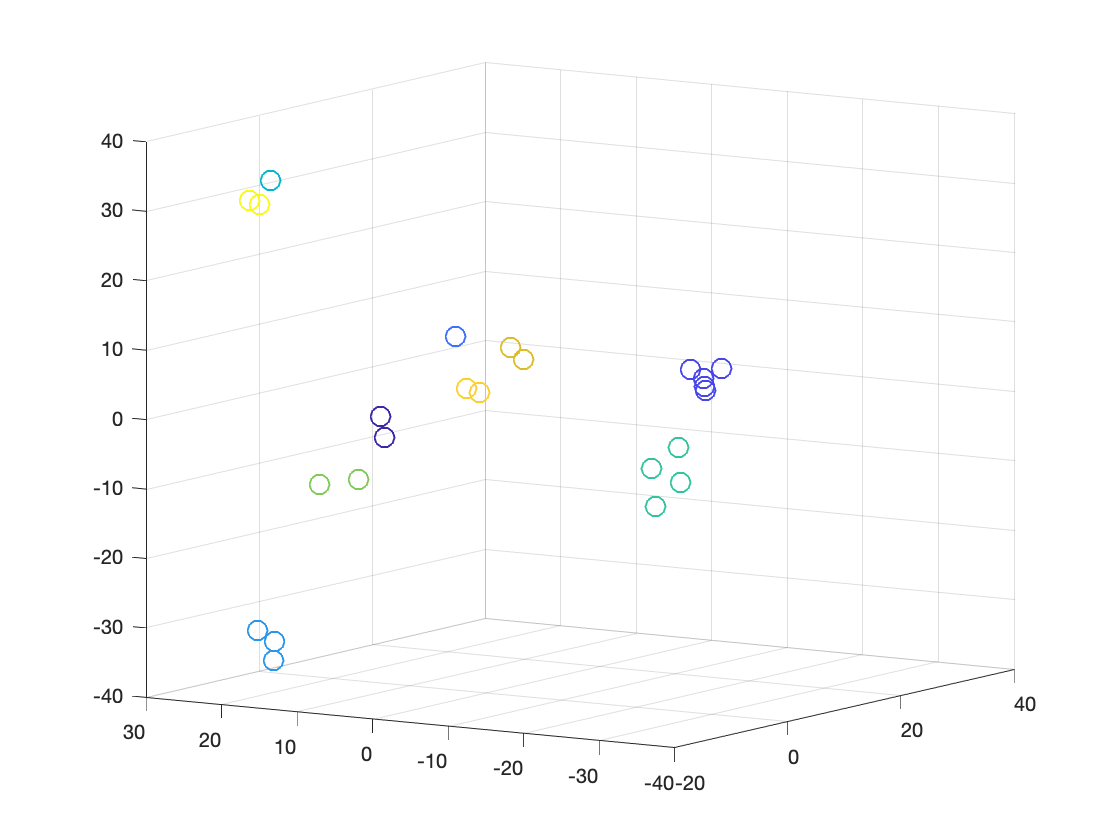



% k-means clustering of the 24 individuals using 1st three Scores for the 4th gen
K = 10;
[idx,c] = kmeans(SCORE(:,1:3),K);
figure; 
scatter3(SCORE(:,1),SCORE(:,2),SCORE(:,3),100, idx)

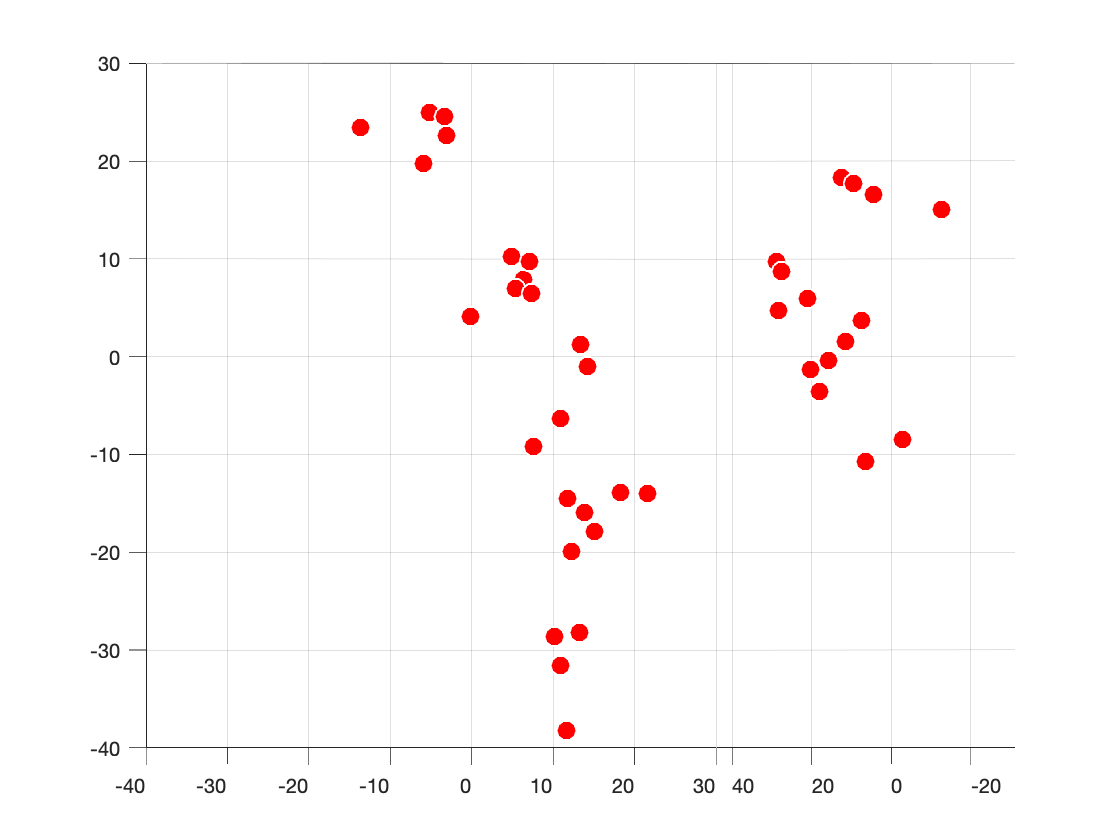



% Do the same for g_tot for all 4 generations, and examine where previous
% generations lie

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(g_tot');
% The number of PCs returned for g_tot are 39 or 40 in columns (depending 
% on parameters), each with 4000 weights along original dimensions
% Scores are the 39/40 observations/individuals projected along the PC axis. 
% Examine the first 3 scores
figure; 
scatter3(SCORE(:,1),SCORE(:,2),SCORE(:,3),100, 'filled','MarkerFaceColor','r',...
                        'MarkerEdgeColor','w')

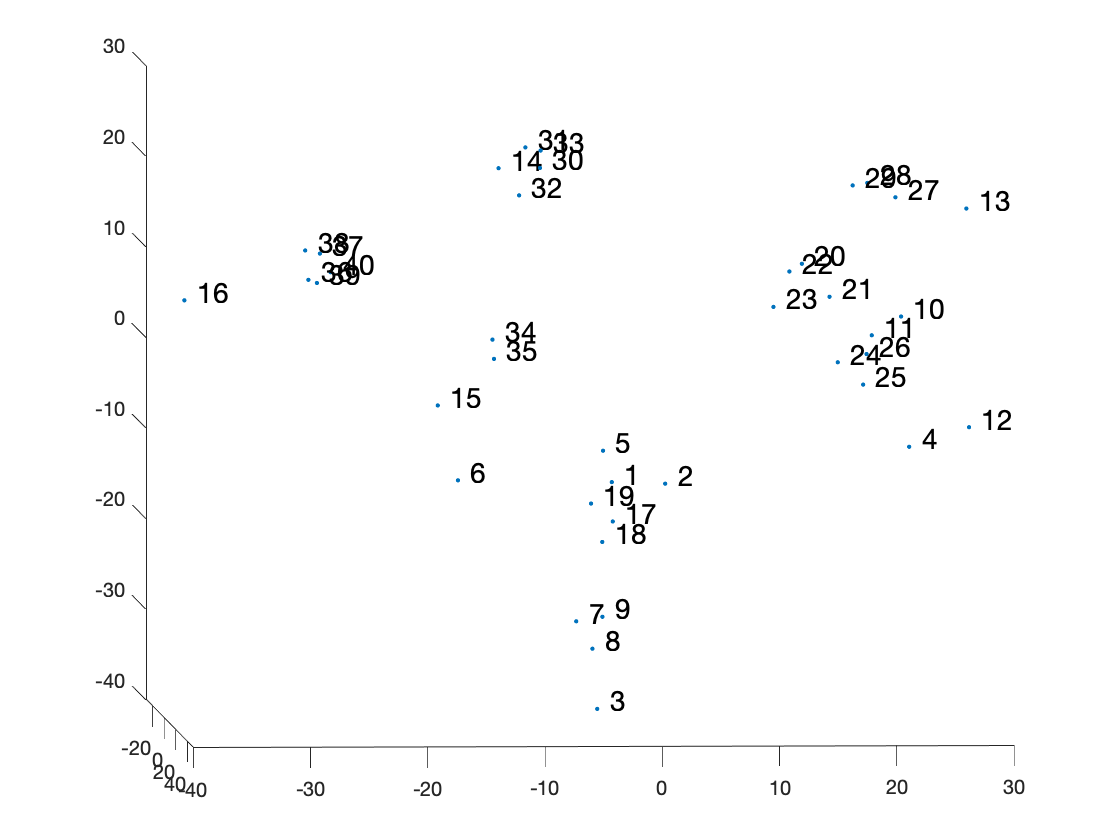


figure;
plot3(SCORE(:,1),SCORE(:,2),SCORE(:,3),'.')
hold on
for i = 1:length(SCORE)
    text(SCORE(i,1)+1,SCORE(i,2)+1,SCORE(i,3)+1,num2str(i),'FontSize',14)
    hold on
end

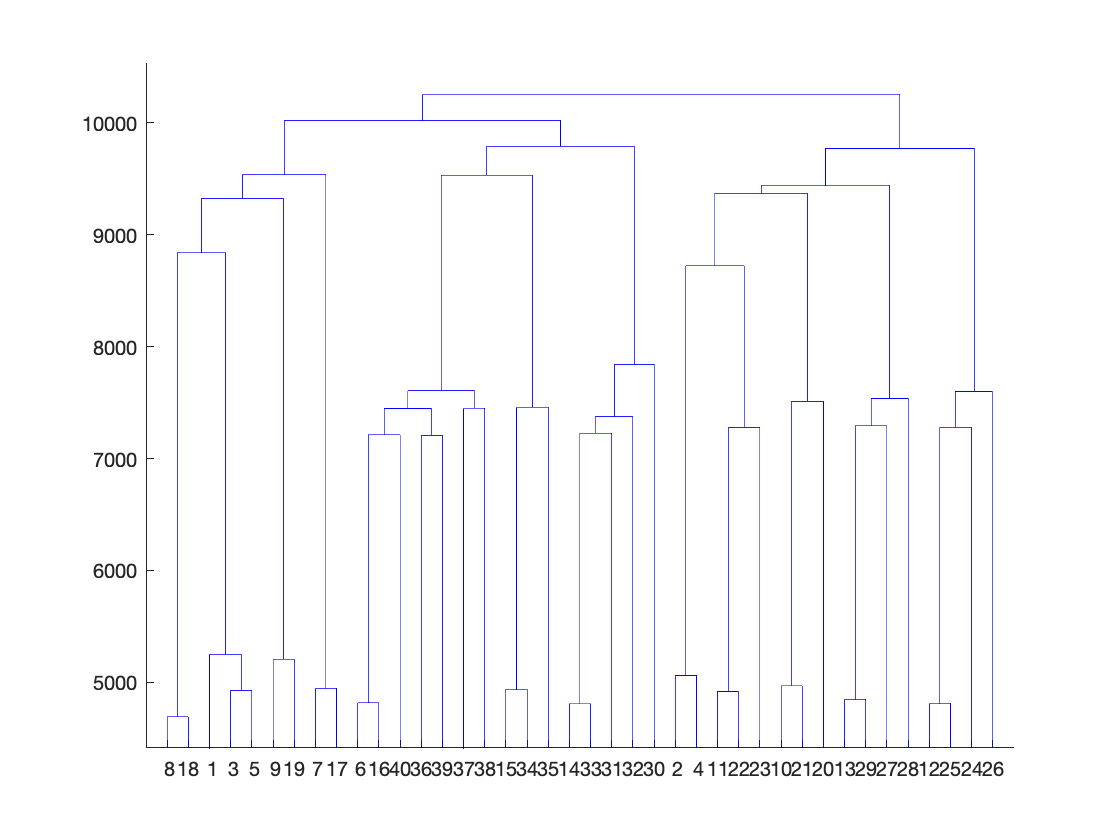




% Linkages in gtot 
Z = linkage(g_tot','complete','squaredeuclidean');
% Z_tot = linkage(g_tot','average','squaredeuclidean');
figure
dendrogram(Z,N_tot);

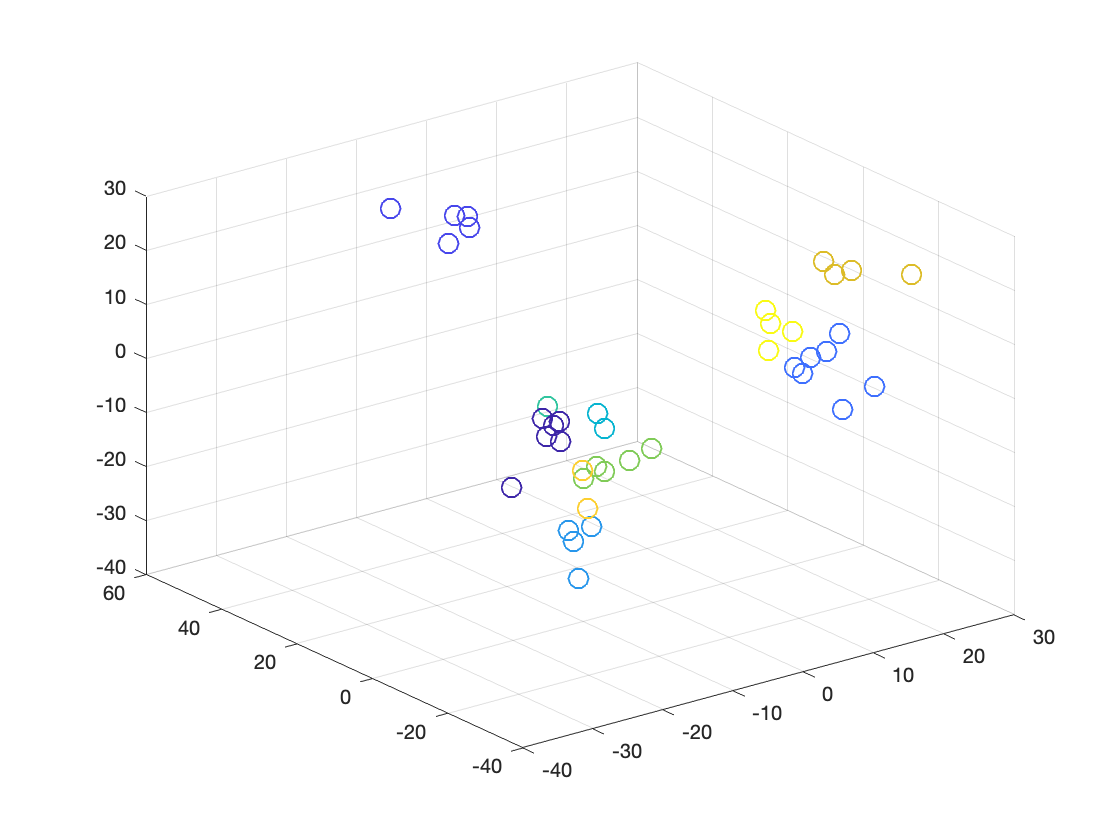



% k-means clustering of the 40 individuals using 1st three Scores for g_tot
K = 10;
[idx,c] = kmeans(SCORE(:,1:3),K);
figure; 
scatter3(SCORE(:,1),SCORE(:,2),SCORE(:,3),100, idx)

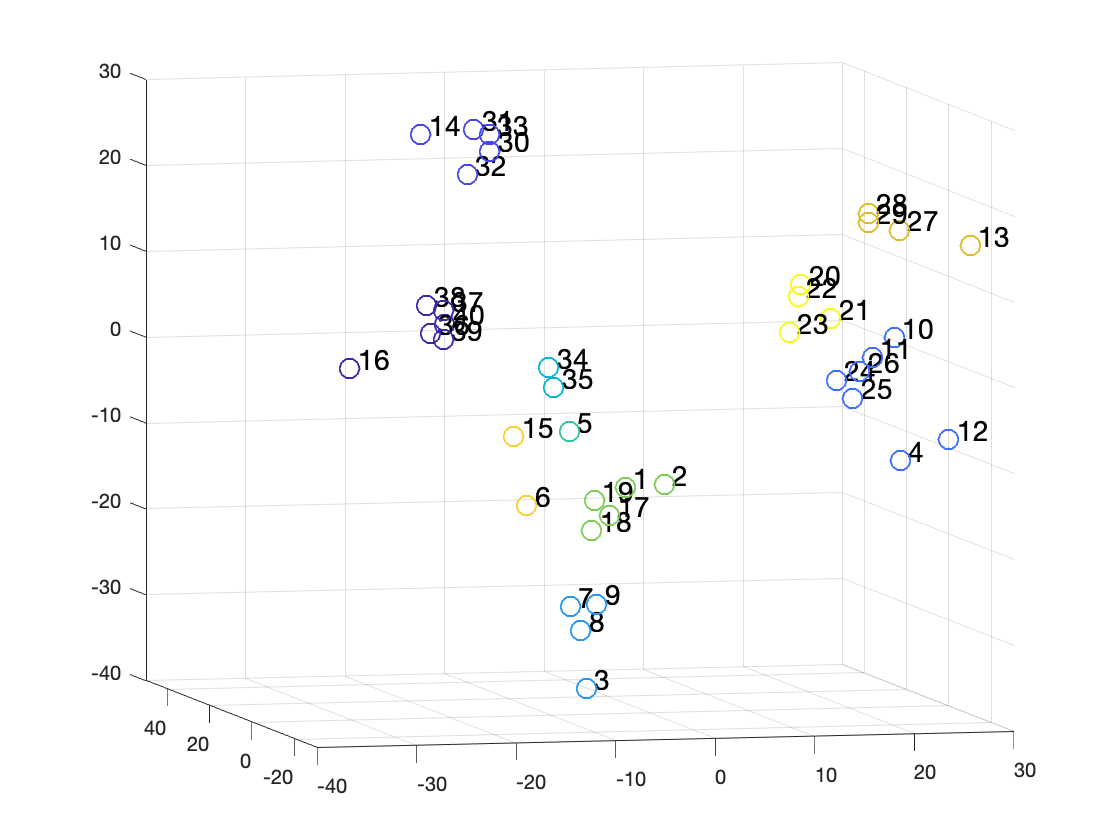


% Plot k-means abd label individuals
% Where do individuals 1 and 2 from 1st Gen, and individuals 3-6 from 2nd
% generation lie?
figure; 
scatter3(SCORE(:,1),SCORE(:,2),SCORE(:,3),100, idx);
hold on
for i = 1:length(SCORE)
    text(SCORE(i,1)+1,SCORE(i,2)+1,SCORE(i,3)+1,num2str(i),'FontSize',14)
    hold on
end

## PCA

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(g4','centered','on','economy','off');

## Group or cluster conditions by PC scores

groupNum = 4;

method_pdist = 'euclidean'; % distance method
method_link = 'average';       % average

core_pdist = pdist(SCORE(:,1:3),method_pdist); % pdist only top 3 PC
score_link = linkage(core_pdist,method_link);

score_clus = cluster(score_link,groupNum);

leafOrder = optimalleaforder(score_link,core_pdist);

## nice colors with color brewer

color for each group 

cmapPCA = brewermap(groupNum,'Set1'); close;

## Plotting

PC scores colored by cluster 

figure
hold on
for currS = 1:size(SCORE,1)
    clusterG = score_clus(currS);
    scatter3(SCORE(currS,1),SCORE(currS,2),SCORE(currS,3),50,'filled','MarkerFaceColor',cmapPCA(clusterG,:),'markeredgecolor','k')
    
    
end

hold off
grid('on')
view(-111,30)

## Dendrogram

all links

figure;
[H,T,outperm] = dendrogram(score_link,'Reorder',leafOrder);
set(H,'LineWidth',3,'Color','k');
set(gca,'fontsize',20,'TitleFontSizeMultiplier', 2.0,'LabelFontSizeMultiplier',1.5);
ylabel('Average distance');

## Dendrogram

Force groupNum

figure;
[H,T,outperm] = dendrogram(score_link,groupNum,'Reorder',leafOrder);
set(H,'LineWidth',3,'Color','k');
set(gca,'fontsize',20,'TitleFontSizeMultiplier', 2.0,'LabelFontSizeMultiplier',1.5);
ylabel('Average distance');